   1

   1



ans =   listener のプロパティ:

       Source: {[1×1 scripts.measureTools.nobinHistogrammer]}
    EventName: 'changeThreshold'
     Callback: @(src,event)makeBinaryMaskImg(this)
      Enabled: 1
    Recursive: 0


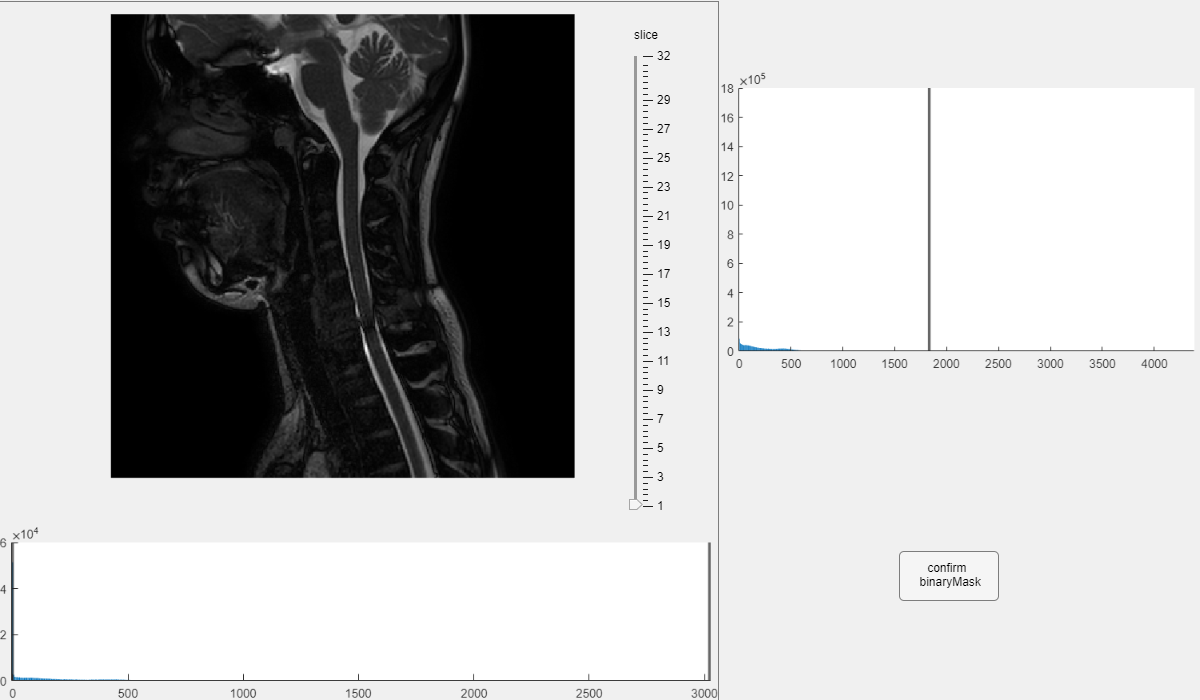

ans =   binaryMaskManager のプロパティ:

          baseFigure: [1×1 Figure]
              parent: [1×1 Figure]
             image3D: [384×384×32 double]
           imgViewer: [1×1 scripts.imageViewer.guiImageViewer]
        histogrammer: [1×1 scripts.measureTools.nobinHistogrammer]
           threshold: []
    binaryMaskResult: []


clc
dcmHandler = scripts.dicomHandler.DICOMHandler();
dcmHandler.readDICOMDIR();
[dcmInfo, dcmImg] = dcmHandler.getPreview();
dcmImgs = dcmHandler.readAllImage();
binaryMaskManager("image3D", dcmImgs)